# **Zernike Polynom Calulator**

Image is always quadratic, so only one number for image size is required!

%Pixelanzahl
Pixel = 1000;


Choose file format for saving (eps is a vector grafic, e.g. for LaTex)

%Image type
PNG = true;
EPS = false;

Which Zernikes shall be plotted?

RmnC =      2    -1


rhoExp =      2     0


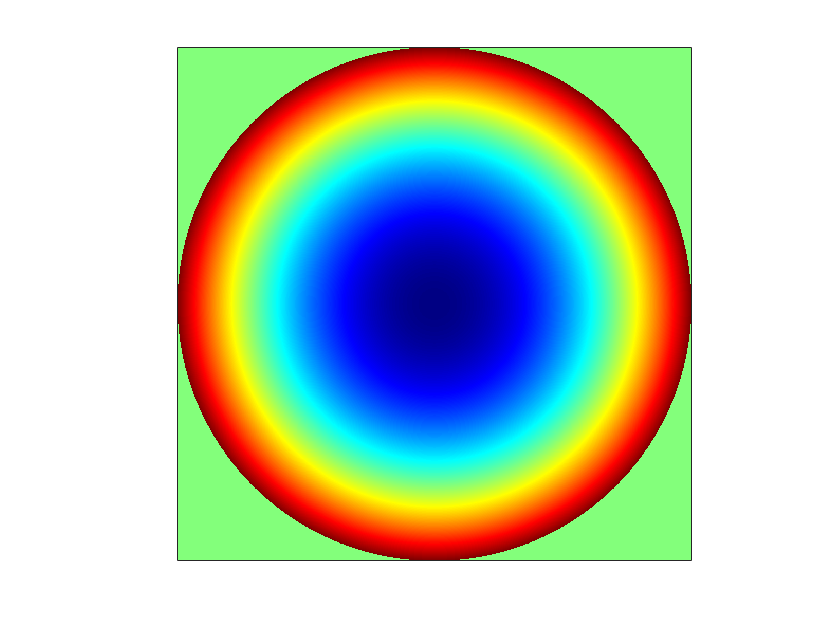

RmnC =      3    -2


rhoExp =      3     1


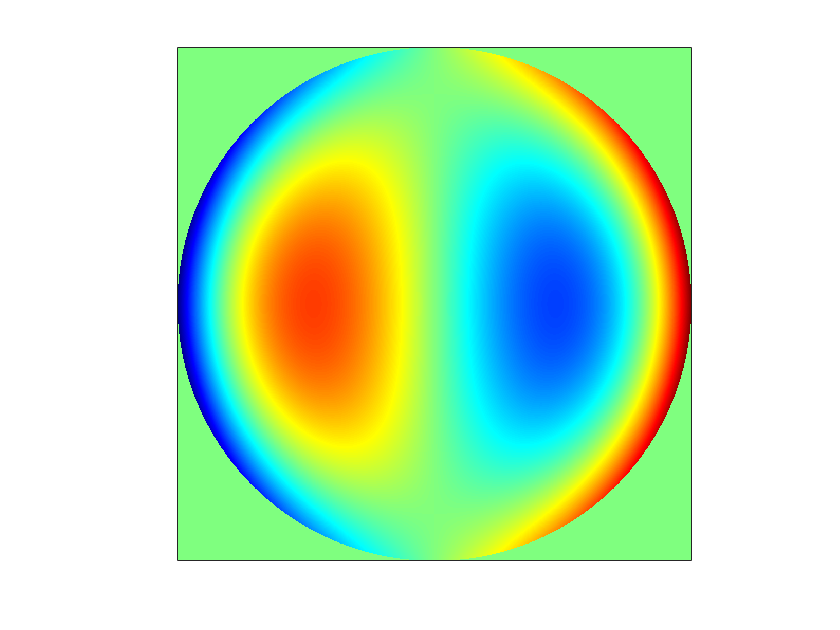

RmnC = 1

rhoExp = 3

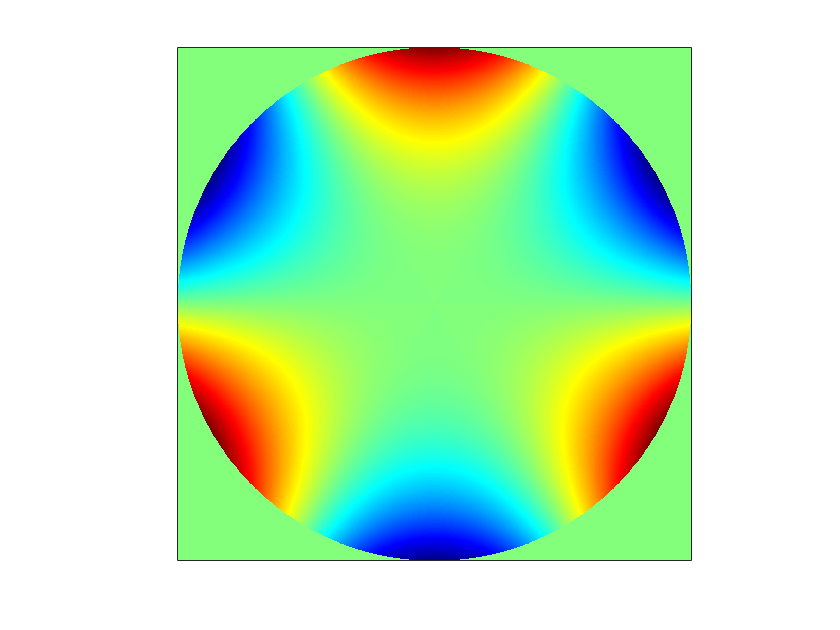

%Zernike Piston
Piston = false;
if Piston
    m(1) = 0;
    n(1) = 0;
end

%Zernike Tip
Tip = false;
if Tip
    m(2) = 1;
    n(2) = 1
end

%Zernike Tilt
Tilt = false;
if Tilt
    m(3) = -1;
    n(3) = 1;
end

%Zernike Defocus
Defocus = true;
if Defocus
    m(4) = 0;
    n(4) = 2;
end

%Zernike Astigmatism
Astigmatism_0 = false;
if Astigmatism_0
    m(5) = 2;
    n(5) = 2;
end

%Zernike Astigmatism
Astigmatism_45 = false;
if Astigmatism_45
    m(6) = -2;
    n(6) = 2;
end

%Zernike Coma_X
Coma_X = true;
if Coma_X
    m(7) = 1;
    n(7) = 3;
end

%Zernike Coma_Y
Coma_Y = false;
if Coma_Y
    m(8) = -1;
    n(8) = 3;
end

%Zernike Trefoil X
Trefoil_X = false;
if Trefoil_X
    m(9) = 3;
    n(9) = 3;
end

%Zernike Trefoil Y
Trefoil_Y = true;
if Trefoil_Y
    m(10) = -3;
    n(10) = 3;
end

%Zernike Spherical
Spherical = false;
if Spherical
    m(11) = 0;
    n(11) = 4;
end

list = [Piston,Tilt,Tip,Defocus,Astigmatism_0,Astigmatism_45,Coma_X,Coma_Y,Trefoil_X,Trefoil_Y,Spherical];

for i=1:length(list)
    if list(i) == true
        [RmnC,rhoExp] = calcPoly(abs(m(i)),n(i))
        myData = calcShape(RmnC,rhoExp,m(i),n(i),Pixel);
        f = figure(i);
        set(gcf,'color','w');
        imagesc(myData);
        set(gca,'XTick',[], 'YTick', [])
        axis square;
        colormap(jet);
        if EPS == true
            fname = ['Zernike' num2str(i) '.eps'];
            exportgraphics(f,fname,"ContentType","vector","BackgroundColor","none")
        end
        if PNG == true
            fname = ['Zernike' num2str(i) '.png'];
            saveas(f,fname)
        end
    end
end